# Lead-lag compensator design with criteria

This live script needs the control toolbox. Once profficient, students will probably find that the methods used in this script are mostly performed using sisotool. 

The script summarises the design techniques covered in the earlier files listed here and uses automated code to undertake the designs and do a compare and contrast:

- **lead_lag_design_with_bode.mlx**

- **lead_design_with_bode.mlx**

- **lag_design_with_bode.mlx**

- **proportional_design_with_bode.mlx**

Users might also like to see  the app: ***lead_lag_design_phase_criteria***.***mlapp*** which is part of the toolbox and automates much of the illustrations shown in the code below so users can focus on results rather than coding.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help Control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Lead and Lag compensator reminders

- Automating the designs

- Compare all the designs

- Subfunction for designs with ramp offset criteria

- Subfunction for designs with step offset criteria

- Subfunction to produce comparison plots for ramp responses

- Subfunction to produce comparison plots for step responses

- Subfunction bodechange.m

## 1. Lead and Lag compensator reminders

This script assumes the following block diagram with system *G(s)* and compensator *M(s)*. The focus here is on a simple lead-lag design approach for *M(s)* based on design criteria or specifications.

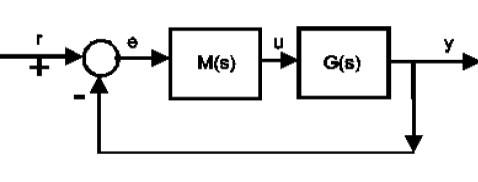

The lead compensator is given as follows and is based on the two criteria: desired PM $\phi$ and desired bandwidth $w_c$ (cross over frequency). The offset is a consequence of  these two criteria and not managed. The full design process is in the file **lead_design_with_bode.**

$\;M\left(s\right)$$=K\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$;        $1\le r\le 10$   

A lag compensator is based on the two criteria: desired PM $\phi$ and desired low frequency gain (typically a ramp error offset). The cross-over frequency $w_c$ falls out automatically from these two criteria. The full design process is in the file **lag_design_with_bode.**

$M\left(s\right)\;=\;\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10p}}\right)$ ;                    $1\le p\le 10$.

A lead-lag compensator is based on the three criteria: desired PM $\phi$, desired low frequency gain (typically a ramp error offset) and desired bandwidth. The full design process is in the file **lead_lag_design_with_bode.**

$M\left(s\right)\;=\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10p}}\right)$$\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$;                    $1\le p\le 10$, $1\le r\le 10$   .

To open the relevant files use the code below:

% run lead_design_with_bode
% run lag_design_with_bode
% run lead_lag_design_with_bode

## 2. Automating the designs  - ramp offset criteria

The design linked to criteria is explicit and therefore can be automated in code which will save time, once students fully understand the design steps. The following sections shows how such code can be developed. The required summary code is provided in a subfunction (section 4) at the end of this file. For ease of development we first use a ramp offset criteria first which means we assume the system includes an integrator. 

Code failures are likely to be linked to unreachable criteria, so the criteria need to be chosen wisely.

### 2.1 Example system and criteria

G=tf(1,[1 5 8 0]);
G2 = tf(1,[1 5 8]);     % without integrator
wc=2;                   % target cross over freq
desiredPM = 60;         % target PM
offsettoramps = 0.2;    % target offset
wmin = wc/100;          % sensible limits for the Bode diagram
wmax = wc*10;

### 2.2 Proportional design

The proportional compensator is used to meet a PM criteria. One can use the file ***margin.m*** to extract the required gain by modifying the original frequency response by the appropriate phase.

[gain,phase,wlist] = bode(G,{wmin,wmax});
[Gm,Pm,wcp,wcg] = margin(gain(:)',phase(:)'-desiredPM,wlist);
M = Gm,wclag=wcp;

**NOTE**: This step assumes the PM is achievable which, for example, it may not be for low order systems whose phase never drops below around -90 degrees..

### 2.3 Lag design

The Lag compensator is used to meet a PM criteria and offset criteria. It uses the gain from the proportional design above and then finds the relevant low freqency gain increase to achieve the desired offset.

plag =1/(dcgain(G2)*M*offsettoramps);
Mlag = M*tf([1,wclag/10],[1,wclag/(10*plag)])  

**NOTE**: In practice some checks are needed to ensure the pole/zero ratio is between 1 and 10 and thus the offset criteria is realistic.

### 2.4 Lead design

The Lead compensator is used to meet a PM criteria and bandwidth criteria. Logically the bandwidth is greater than that achieved with the lag, but not too much greater or it will imply significant over actuation.

[gainGwc,phaseGwc] = bode(G,wc);
uplift = -180 - phaseGwc +desiredPM;
upliftrad=uplift*pi/180;
r = (sin(upliftrad)+1)/(1-sin(upliftrad));
sr=sqrt(r);
K= sr/gainGwc;
zero = wc/sr;
pole = wc*sr;
Mlead = K*tf([1,zero],[1,pole])

**NOTE**: In practice some checks are needed to ensure the pole/zero ratio is between 1 and 10 and thus the bandwidth criteria is realistic.

### 2.5 Lead-lag design

The Lead-lag compensator is used to meet all 3 criteria and begins from the lead design above, adding a lag component to meet the offset criteria. 

p= 1/(dcgain(Mlead)*dcgain(G2)*offsettoramps);   %gainrecovery
Mlag2 = tf([1,wc/10],[1,wc/(p*10)]);
Mleadlag=Mlead*Mlag2

### 2.6 Automating all the designs

For simplicity, all the code above can be captured in a single file (see section 4). 

[M,Mlag,Mlead,Mleadlag]=leadlagdesignmaster(G,wc,desiredPM,offsettoramps)

### 2.7 Automating all the designs with step offset criteria

When the offset criteria is based on a step, this works for systems which do not include an integrator and needs a slightly different lag design, for example the code of sections 2.3 and 2.5 above is modified as follows:

% plag =((1/offsettosteps)-1)/(dcgain(G)*M);  % for section 2.3
% p=((1/offsettosteps)-1)/(dcgain(Mlead)*dcgain(G));  % for section 2.5
% [M,Mlag,Mlead,Mleadlag]=leadlagdesignmaster2(G,wc,desiredPM,offsettosteps)

## 3. Examples with plotting comparisons

Having undertaken the designs, the next step is to undertake comparisons of behaviour:

- What can we see in the Bode diagrams?

- What can we see in the closed-loop responses? 

Again for simplicity and speed, a subfunction is constructed to produce the desired plots.

**Note**: For systems with an integrator where we have used offset to ramp as a  criteria, it is reasonable to plot responses to a ramp input.

### 3.1. Systems with an integrator

disp(['**********************************']);
disp(' ')
disp('Section 3.1 below')
disp(' ');
G=tf(1,[1 5 8 0]);
G2 = tf(1,[1 5 8]);     % without integrator
wc=2;                   % target cross over freq
desiredPM = 60;         % target PM
offsettoramps = 0.2;    % target offset
endtime=10;

% G=tf([10 20],poly([0 -1 -4 -4]));

M = 7.0771

% G2 = tf([10 20],poly([-1 -4 -4]));
% wc  =1.9;
% desiredPM = 60; % target PM
% offsettoramps = 0.2;
% endtime =5;

Mlag =
 
  7.077 s + 0.5948
  ----------------
    s + 0.01487
 
Continuous-time transfer function.
Model Properties



[M,Mlag,Mlead,Mleadlag]=leadlagdesignmaster(G,wc,desiredPM,offsettoramps)
leadlagdesignoverlays(G,M,Mlag,Mlead,Mleadlag,endtime)

### 3.2 Systems without an integrator

disp(['**********************************']);
disp(' ')
disp('Section 3.2 below')
G=tf([10 20],poly([-1 -4 -4]));
wc  =20;
desiredPM = 60; % target PM
offsettosteps = 0.02;
endtime=1.5;


Mlead =
 
  44.36 s + 43.08
  ---------------
     s + 4.119
 
Continuous-time transfer function.
Model Properties


[M,Mlag,Mlead,Mleadlag]=leadlagdesignmaster2(G,wc,desiredPM,offsettosteps)
leadlagdesignoverlays2(G,M,Mlag,Mlead,Mleadlag,endtime)


## 4. Subfunction for designs with ramp offset criteria

Used to make the axes and ticks bolder and larger.

% This file develops proportional, lag, lead and lead-lag compensators
% based solely on criteria. Assumes the criteria are achievable.
%

Mleadlag =
 
  44.36 s^2 + 51.95 s + 8.616
  ---------------------------
    s^2 + 4.171 s + 0.2154
 
Continuous-time transfer function.
Model Properties


% M         proportional design uses only the PM criteria
% Mlag      Lag uses PM and offset criteria
% Mlead     Lead uses PM and bandwidth criteria

M = 7.0771

Mlag =
 
  7.077 s + 0.5948
  ----------------
    s + 0.01487
 
Continuous-time transfer function.
Model Properties

Mlead =
 
  44.36 s + 43.08
  ---------------
     s + 4.119
 
Continuous-time transfer function.


% Mleadlag  uses all 3 criteria
%
% wc is target bandwidth
% desiredPM is target phase margin
% offsettoramps is desired offset
%
% Assumes system G includes an integrator and is open-loop stable
%
%  [M,Mlag,Mlead,Mleadlag]=leadlagdesignmaster(G,wc,desiredPM,offsettosteps)
%

function [M,Mlag,Mlead,Mleadlag]=leadlagdesignmaster(G,wc,desiredPM,offsettoramps)

[n,d]= tfdata(G,'v');

**********************************


G2 = tf(n,d(1:end-1));

wmin=wc/100;

Section 3.1 below


wmax=wc*10;



% proportional design
[gain,phase,wlist] = bode(G,{wmin,wmax});
[Gm,Pm,wcp,wcg] = margin(gain(:)',phase(:)'-desiredPM,wlist);
M = Gm;wclag=wcp;

% lag design
plag =1/(dcgain(G2)*M*offsettoramps);
Mlag = M*tf([1,wclag/10],[1,wclag/(10*plag)])  ;
if plag>10;
    plag =10; 
    Mlag = M*tf([1,wclag/10],[1,wclag/(10*plag)]);
    disp('****************************');
    disp('Offset criteria not achievable with a sensible lag: reseting to');

M = 7.0771

Mlag =
 
  7.077 s + 0.5948
  ----------------
    s + 0.01487
 
Continuous-time transfer function.
Model Properties

Mlead =
 
  44.36 s + 43.08
  ---------------
     s + 4.119
 
Continuous-time transfer function.


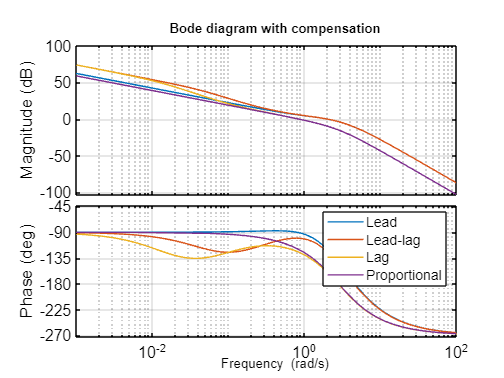

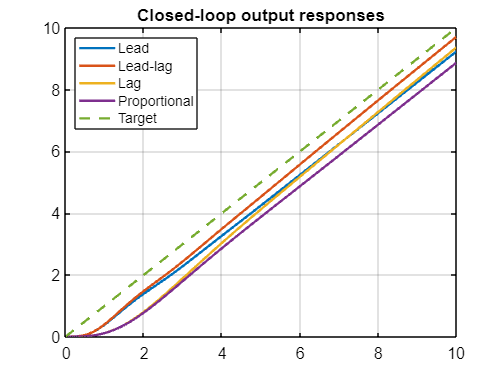

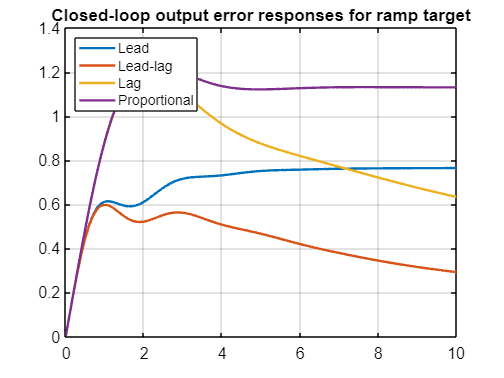

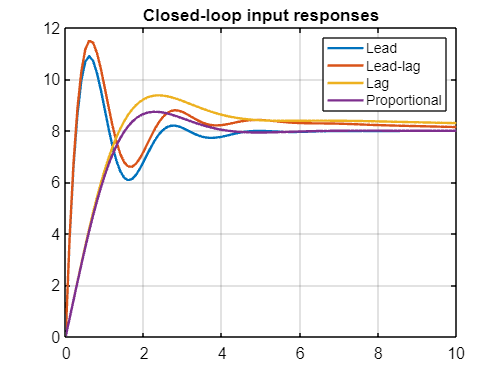

    offsettoramps = 1/(dcgain(G2*Mlag))

elseif plag<1;
    plag =1; 
    disp('****************************');

**********************************


    disp('Lag not needed to meet offset criteria')

    Mlag = M;

Section 3.2 below


end


% lead design
[gainGwc,phaseGwc] = bode(G,wc);
uplift = -180 - phaseGwc +desiredPM;
if uplift>55;

M = 4.7705

Mlag =
 
  4.771 s + 2.766
  ---------------
    s + 0.07056
 
Continuous-time transfer function.
Model Properties

Mlead =
 
  89.34 s + 828.9
  ---------------
     s + 43.11
 
Continuous-time transfer function.


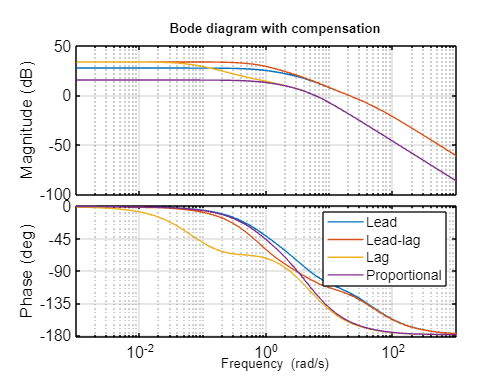

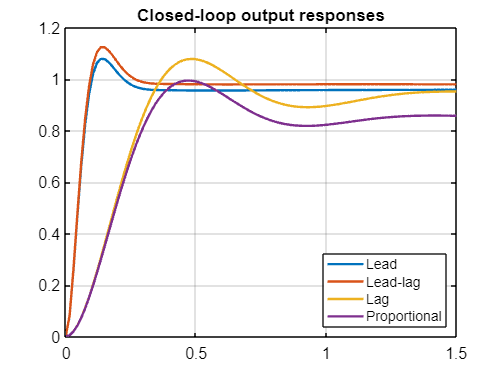

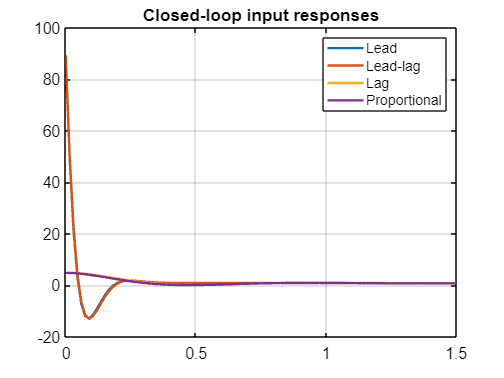

    disp('****************************');

    disp('Lead not enough to meet bandwidth criteria: reseting wc to')
    wc = wclag*2
    [gainGwc,phaseGwc] = bode(G,wc);
    uplift = -180 - phaseGwc +desiredPM;
end
upliftrad=uplift*pi/180;
r = (sin(upliftrad)+1)/(1-sin(upliftrad));
sr=sqrt(r);
K= sr/gainGwc;
zero = wc/sr;
pole = wc*sr;
Mlead = K*tf([1,zero],[1,pole]);

% lead-lag design
p= 1/(dcgain(Mlead)*dcgain(G2)*offsettoramps);   %gainrecovery
Mlag2 = tf([1,wc/10],[1,wc/(p*10)]);
Mleadlag=Mlead*Mlag2;

end

## 5. Subfunction for designs with step offset criteria

Used to make the axes and ticks bolder and larger.

% This file develops proportional, lag, lead and lead-lag compensators
% based solely on criteria. Assumes the criteria are achievable.
%
% M         proportional design uses only the PM criteria
% Mlag      Lag uses PM and offset criteria
% Mlead     Lead uses PM and bandwidth criteria
% Mleadlag  uses all 3 criteria
%
% wc is target bandwidth
% desiredPM is target phase margin
% offsettosteps is desired offset
%
% Assumes system G includes no integrator and is open-loop stable
%
%  [M,Mlag,Mlead,Mleadlag]=leadlagdesignmaster2(G,wc,desiredPM,offsettosteps)
%

function [M,Mlag,Mlead,Mleadlag]=leadlagdesignmaster2(G,wc,desiredPM,offsettosteps)

wmin=wc/100;
wmax=wc*10;
endtime = (1/wc)*30;

% proportional design
[gain,phase,wlist] = bode(G,{wmin,wmax});
[Gm,Pm,wcp,wcg] = margin(gain(:)',phase(:)'-desiredPM,wlist);
M = Gm;wclag=wcp;

%  lag design and checks for sensible criteria
plag =((1/offsettosteps)-1)/(dcgain(G)*M);
Mlag = M*tf([1,wclag/10],[1,wclag/(10*plag)]);
if plag>10;
    plag =10; 
    Mlag = M*tf([1,wclag/10],[1,wclag/(10*plag)]);
    disp('****************************');
    disp('Offset criteria not achievable with a sensible lag: reseting to');
    offsettosteps = 1/(1+dcgain(G*Mlag))
elseif plag<1;
    plag =1; 
    disp('****************************');
    disp('Lag not needed to meet offset criteria')
    Mlag = M;
end


% lead design
[gainGwc,phaseGwc] = bode(G,wc);
uplift = -180 - phaseGwc +desiredPM;
if uplift>55;
    disp('****************************');
    disp('Lead not enough to meet bandwidth criteria: reseting wc to')
    wc = wclag*2
    [gainGwc,phaseGwc] = bode(G,wc);
    uplift = -180 - phaseGwc +desiredPM;
end

upliftrad=uplift*pi/180;
r = (sin(upliftrad)+1)/(1-sin(upliftrad));
sr=sqrt(r);
K= sr/gainGwc;
zero = wc/sr;
pole = wc*sr;
Mlead = K*tf([1,zero],[1,pole]);

% lead-lag design
p=((1/offsettosteps)-1)/(dcgain(Mlead)*dcgain(G));
Mlag2 = tf([1,wc/10],[1,wc/(p*10)]);
Mleadlag=Mlead*Mlag2;

end

## 6. Produce comparison plots for ramp responses

% This file compares lag, lead and lead-lag compensators
% 
% Assumes system G includes an integrator and is open-loop stable
%
%  leadlagdesignoverlays(G,M,Mlag,Mlead,Mleadlag,endtime)
%
function leadlagdesignoverlays(G,M,Mlag,Mlead,Mleadlag,endtime)

% Plot Bode diagram
figure
bode(G*Mlead,G*Mleadlag, G*Mlag, G*M);grid on; 
legend('Lead','Lead-lag','Lag','Proportional')
title('Bode diagram with compensation');
bodechange

% Closed-loop step responses
figure
t=linspace(0,endtime,101);
GcMlead=feedback(G*Mlead,1);
GcMleadlag=feedback(G*Mleadlag,1);
GcMlagonly=feedback(G*Mlag,1);
GcM=feedback(G*M,1);
ylead = lsim(GcMlead,t,t);
yleadlag = lsim(GcMleadlag,t,t);
ylag = lsim(GcMlagonly,t,t);
ykp = lsim(GcM,t,t);
plot(t,ylead,t,yleadlag,t,ylag,t,ykp,'linewidth',2);hold on
plot(t,t,'--','LineWidth',2)
title('Closed-loop output responses')
legend('Lead','Lead-lag','Lag','Proportional','Target','Location','Northwest')
grid
bodechange

figure
plot(t,t'-ylead,t,t'-yleadlag,t,t'-ylag,t,t'-ykp,'linewidth',2);
title('Closed-loop output error responses for ramp target')
legend('Lead','Lead-lag','Lag','Proportional','Location','Northwest')
grid
bodechange


figure
GcMleadu=feedback(Mlead,G);
GcMleadlagu=feedback(Mleadlag,G);
GcMlagonlyu=feedback(Mlag,G);
GcMu=feedback(M,G);
ulead = lsim(GcMleadu,t,t);
uleadlag = lsim(GcMleadlagu,t,t);
ulag = lsim(GcMlagonlyu,t,t);
ukp = lsim(GcMu,t,t);

plot(t,ulead,t,uleadlag,t,ulag,t,ukp,'linewidth',2);
title('Closed-loop input responses')
legend('Lead','Lead-lag','Lag','Proportional')
grid
bodechange


end

## 7. Comparison plots for step responses

% This file compares lag, lead and lead-lag compensators
% 
% Assumes system G includes an integrator and is open-loop stable
%
%  leadlagdesignoverlays2(G,M,Mlag,Mlead,Mleadlag,endtime)
%
function leadlagdesignoverlays2(G,M,Mlag,Mlead,Mleadlag,endtime)

% Plot Bode diagram
figure
bode(G*Mlead,G*Mleadlag, G*Mlag, G*M);grid; 
legend('Lead','Lead-lag','Lag','Proportional')
title('Bode diagram with compensation');
bodechange

% determine closed-loop TF and step responses
figure
t=linspace(0,endtime,101);
GcMlead=feedback(G*Mlead,1);
GcMleadlag=feedback(G*Mleadlag,1);
GcMlagonly=feedback(G*Mlag,1);
GcM=feedback(G*M,1);
ylead = step(GcMlead,t);
yleadlag = step(GcMleadlag,t);
ylag = step(GcMlagonly,t);
ykp = step(GcM,t);

plot(t,ylead,t,yleadlag,t,ylag,t,ykp,'linewidth',2);
title('Closed-loop output responses')
legend('Lead','Lead-lag','Lag','Proportional','Location','Southeast')
grid
bodechange

figure
GcMleadu=feedback(Mlead,G);
GcMleadlagu=feedback(Mleadlag,G);
GcMlagonlyu=feedback(Mlag,G);
GcMu=feedback(M,G);
ulead = step(GcMleadu,t);
uleadlag = step(GcMleadlagu,t);
ulag = step(GcMlagonlyu,t);
ukp = step(GcMu,t);

plot(t,ulead,t,uleadlag,t,ulag,t,ukp,'linewidth',2);
title('Closed-loop input responses')
legend('Lead','Lead-lag','Lag','Proportional')
grid
bodechange

end


## 8. Subfunction bodechange.m to make axis clearer

function bodechange
h=findobj(get(gcf, 'children'), 'Type', 'axes');

for i=1:length(h)
    set(h(i), 'fontSize', 13)
    set(h(i), 'XColor', [0 0 0])
     set(h(i), 'YColor', [0 0 0])
end
end
    